# FEMM Basic Short Course

**Objective**

- Introduce basic manipulation in FEMM and the process flow for magnetic FE analysis.

- Automate the flow process using MATLAB command.

To achieve the objective, we will try to simulate an AC motor where the following will be learned and observed:

- Winding distribution in AC machine.

- AC current definition

- Rotating magnetic field, RMF

- Inductance and torque computation.

## Case study:

### FEMM

FEMM is a finite element analysis (FEA) software tool specifically designed for simulating and analyzing electromagnetic and magnetic field problems. FEMM is primarily used in the field of electrical engineering and electromagnetics to model and solve problems related to the behavior of magnetic fields, such as in transformers, motors, generators, and other electromagnetic devices.

FEMM is open-source software, which means it's freely available for users to download and use, making it accessible to a wide range of individuals and organizations involved in electromagnetic and magnetic field analysis.

The software can be downloaded from its website: [HomePage:Finite Element Method Magnetics (femm.info)](https://www.femm.info/wiki/HomePage)

The manual explaining all the commands and utilization of FEMM can be found at: [Documentation:Finite Element Method Magnetics (femm.info)](https://www.femm.info/wiki/Documentation/)

Some basic tutorials could also be found at the same place.

### SynRM machine

We will be using a solid rotor Synchronous Reluctance machine (SynRM) as example to illustrate the capacility of FEMM as a magnetic FEA tools. The motor that we are modelling will be explained later.

## Introduction

As like any other FEA simulation tools, there are a flow process or pipeline that need to be followed to complete a FE analysis project. Following order, they are:

- Definition problem types

- Drawing the geometry

- Defining region

- Importing materials to the project

- Defining electrical circuit if any

- Affecting the materials to the region and circuit

- Defining boundary layer

- Meshing

- Running solver

- Post-processing: analyzing the results

## 1. Problem type definition 

The problem that we are developing FE for is a magnetic problem with the following definition:

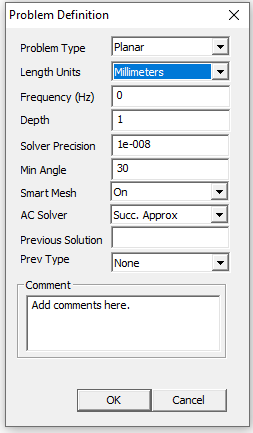

## 2.Drawing the geometry

The motor that we are studying in this example case is  a SynRM motor. 

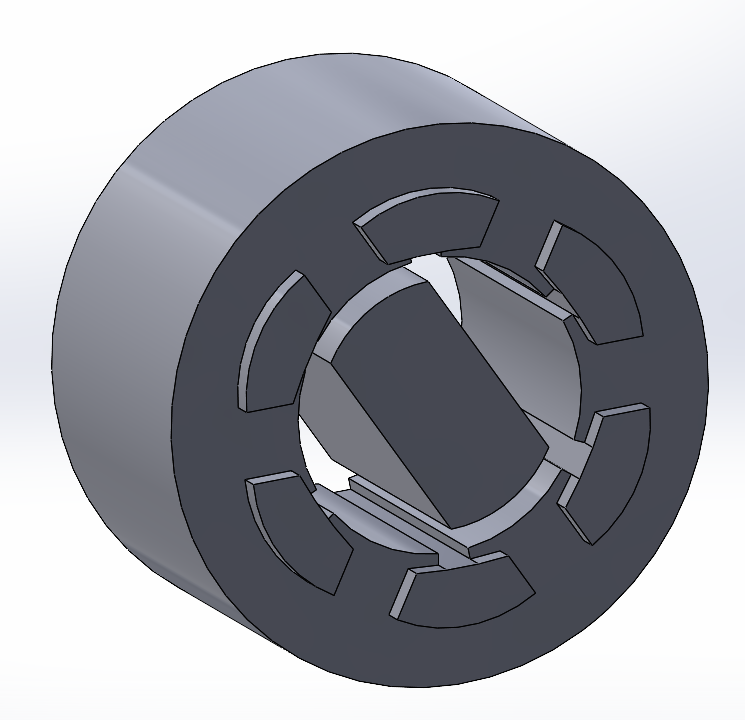 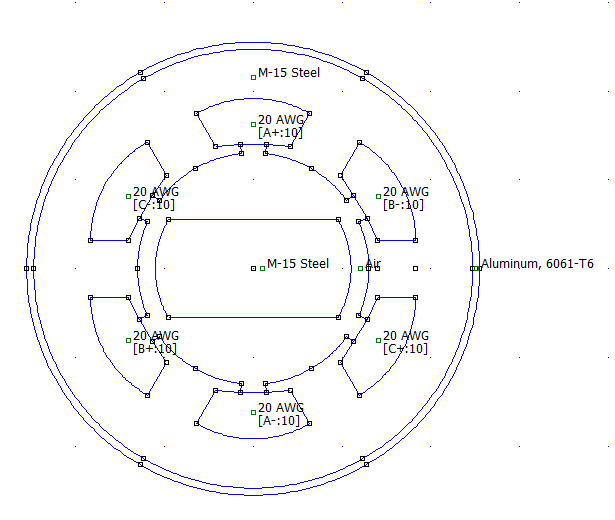

The figure on the left shows the 3D rendening of the machine while the right figure is the figure from FEMM. The machine is a 3-phase AC machine with 1 pair pole (2 poles) per phase evenly distributed on the stator. The rotor is a solid salient rotor. The core material (both stator and rotor are made of M15 soft magnetic steel) and the conductors are of 20AWG size copper with 10 turns in each slot.

There are 3 methods that can be used to draw  the geometry:

### 1. Manually entering the coordinate and sections creation

This is the most basic method, also known for those who are familiar with CAD softwares. You need to enter points, then connect the points to create segments and arches that build the complete machine geometry. Below are the coordinates of the machine for one pole of a single phase.The coordinates can be found in the files "SynRM_1polephase.FEM". Open the file using MATLAB.

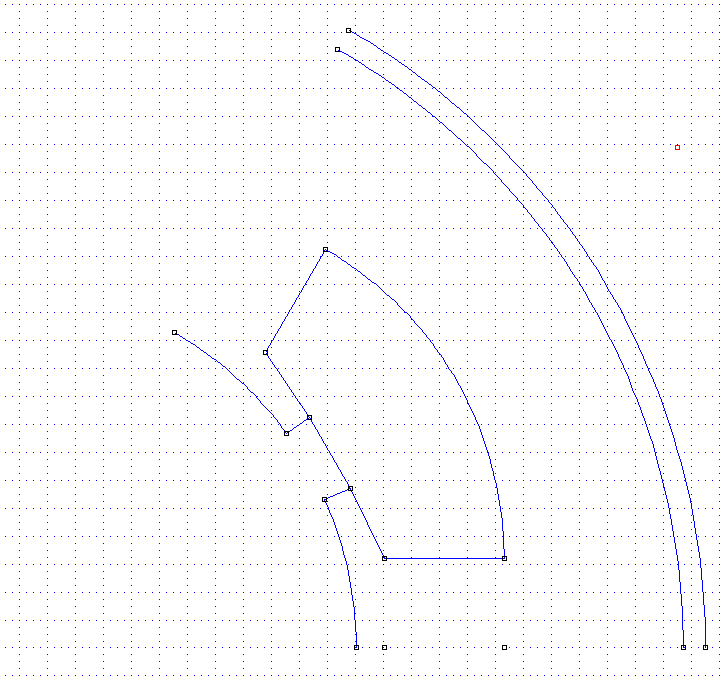 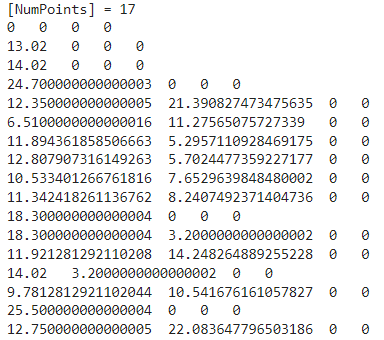

17 points are needed to create 1 pole of a single phase of the machine. The coordinates are arranged as (x-coordinate, y-coordinate, 0, 0). Enter all the points by clicking the 'node' button and push TAB. The following pop-up will appear and enter your coordinates. Enter all 17 points given.

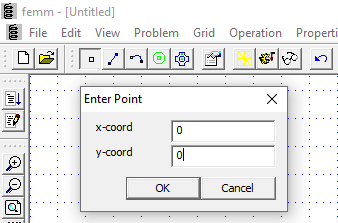

Once all the points are entered, the segments and arcs can be created. There are 7 segments and 5 arcs on 1 pole of a single phase of the machine as shown in the figure below (also found in the same file "SynRM_1polephase.FEM"). 

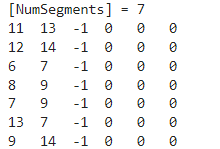  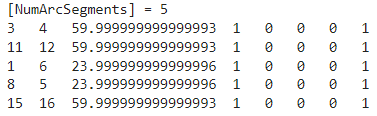

To create the segments, click on the button segments, an dconnect the nodes necessary. The first 2 lines in the segment table refers to the node that should be connected. For example, the first segments connect the node 11 and node 13 (Figure left). The same is true for arches, in the example, the first arches is connected by node 3 and node 4 (Figure right). The third value is the angle of the arc. Connect all the segments and archesuntil you get the drawing below:

Now, that we have drawn 1 pole of a signle phase, we can copy and rotate the geometry drawn to complete the full 360 degree rotation. To do so, select all the points by selecting all the segment and arcs by "select region". This need to be done for each segments and arc segments separately. Then, click "copy" and enter the angle 60 degree and number of copy 6 in the pop-up window.

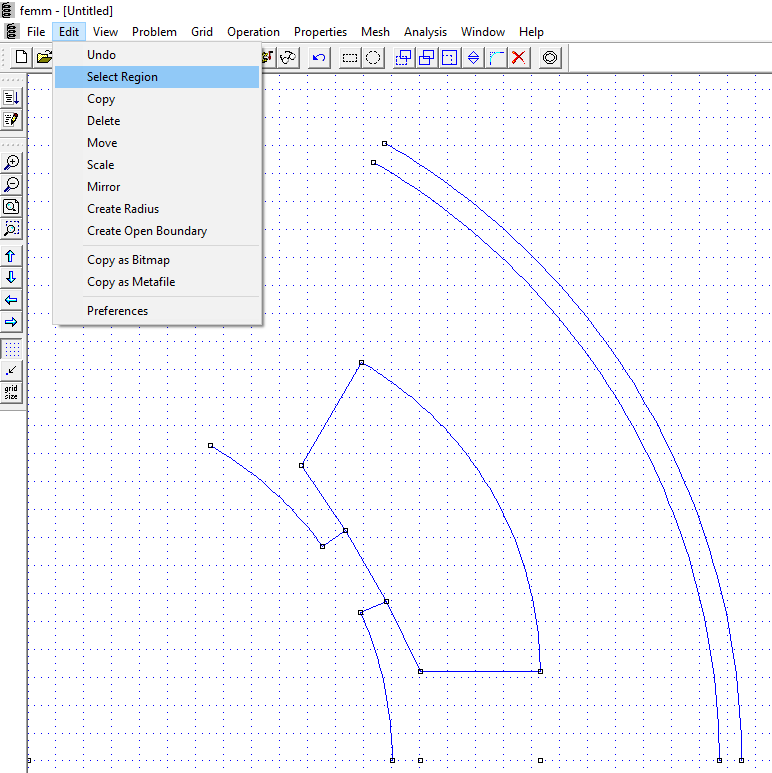  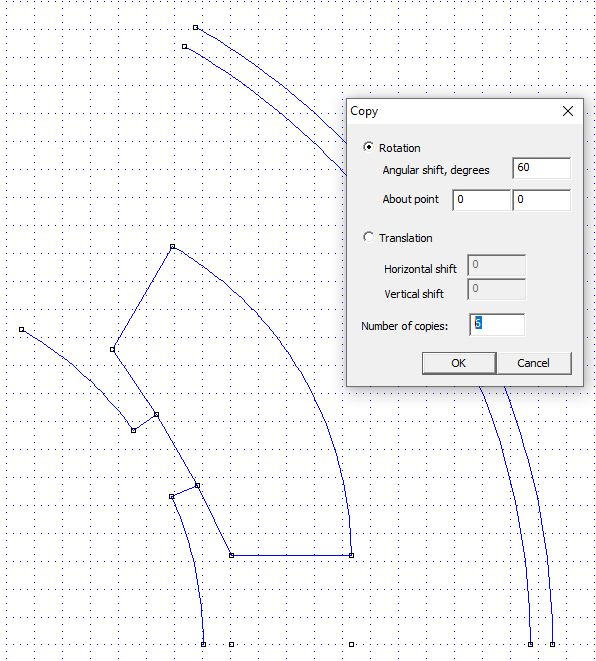

On the left below is the figure of the result after copying the arc. On the right after copying the segments as well. Now, we have the complete geometry.

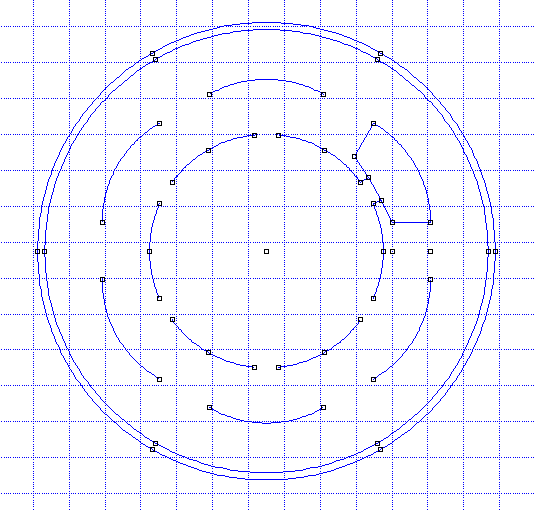  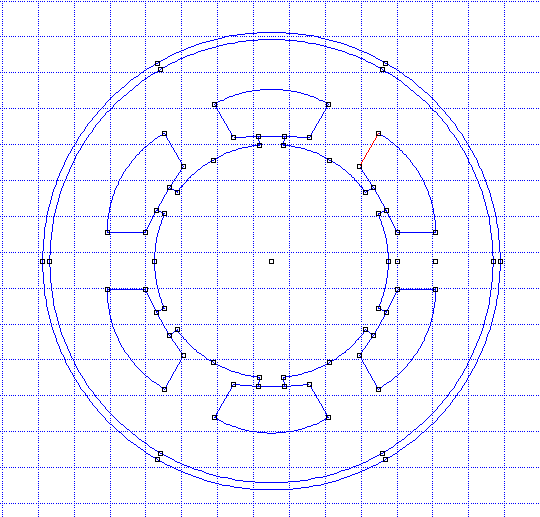

### 2. Import DXF from a 3D drawing 

This is a method that is useful if we already have a 3D drawing of an existing machine that we want to study. This is usually used when there is iteration to the design due to manufacturing or assembly constraints that require a certain modifications onto the magnetic structure. Therefore, a magnetic verification study is necessary to validate or verify the consequence of the modiifcations. Such example will be treated in a more advance module in the future.

### 3. Definition and generation of geometry by MATLAB code

FEMM is capable to interact with MATLAb where codes can be written to execute the same commands that we did manually previously. Leveraging the power of programming with parametrization of the geometry, we can analyze the machine with dimensional and circuit variation without having to redraw and redefine all over manually.

Each step executed done manually previously has the equivalent code that can be found in the manual ([Documentation:Finite Element Method Magnetics (femm.info)](https://www.femm.info/wiki/Documentation/)). Below are the codes:

Open FEMM in background and define problem definition

openfemm;
newdocument(0);
mi_probdef(0,'millimeters','planar',1e-8,70,30);

 Next, we could define the variables related to the design of the machine. Here we will parametrize the dimensions to allow for future easy modifications.

% Define variable
% Stator geometric parameter
p = 1;                           % pair pole
phi = 3;                         % phase
N_slot = 2*p*3;                  % number of slot
theta_pole = 2*pi/N_slot;        % 1 pole angle
theta_pole_deg = (2*pi/N_slot)*180/pi;   % 1 pole angle
theta_tooth_fan = 0.8*theta_pole; % teeth faning angle
theta_tooth_fan_deg = theta_tooth_fan*180/pi; 
theta_so = (2*pi-N_slot*theta_tooth_fan)/N_slot; % slot opening fanning angle
theta_so_deg = theta_so*180/pi; 
l_tooth = 6.40;                  % tooth width original 3.40
e_shim = 1.00;                   % height tooth base
h_yoke_stat = l_tooth;              % stator yoke height
R_int_stat = 26.04/2;            % stator interior radius
R_ext_stat = 43.40/2 + l_tooth - 3.40;            % stator exterior radius
thickness_case = 0.8;            % casing thickness

% Rotor geometric parameter
airgap = 2;     % airgap in mm
l_rotor = 2*l_tooth; %thickness of rotor
theta_rotor = 360/N_slot;   % angular span rotor
x_rotor = R_int_stat - airgap;  %radius rotor

Then, we will create the nodes by defining the position of each node, then create the nodes using the command mi-addnode(x,y)

%% STATOR
% Define points nodes
x1 = 0; y1 = 0;
x2 = R_int_stat; y2 = 0;
x3 = R_int_stat + e_shim; y3 = 0;
x4 = R_ext_stat; y4 = 0;
x5 = x4*cos(theta_pole); y5 = x4*sin(theta_pole);
x6 = x2*cos(theta_pole); y6 = x2*sin(theta_pole);
x7 = x2*cos(theta_tooth_fan/2); y7 = x2*sin(theta_tooth_fan/2);
x8 = x3*cos(theta_tooth_fan/2); y8 = x3*sin(theta_tooth_fan/2);
x9 = x2*cos((theta_tooth_fan/2)+(theta_so)); y9 = x2*sin((theta_tooth_fan/2)+(theta_so));
x10 = x3*cos((theta_tooth_fan/2)+(theta_so)); y10 = x3*sin((theta_tooth_fan/2)+(theta_so));
x11 = x4-h_yoke_stat; y11 =0;
x12 = x11; y12 = l_tooth/2;
xmid_theta_slot = (l_tooth/2)/(tan(theta_pole/2));  % center pole slot
ymid_theta_slot = l_tooth/2;
x13 = (x12-xmid_theta_slot)*cos(theta_pole)+xmid_theta_slot; y13 = (x12-xmid_theta_slot)*sin(theta_pole)+ymid_theta_slot;
x14 = x3; y14 = l_tooth/2;
x15 = (x14-xmid_theta_slot)*cos(theta_pole)+xmid_theta_slot; y15 = (x14-xmid_theta_slot)*sin(theta_pole)+ymid_theta_slot;
x16 = R_ext_stat+thickness_case; y16 = 0;
x17 = (R_ext_stat+thickness_case)*cos(theta_pole); y17 = (R_ext_stat+thickness_case)*sin(theta_pole);

% create node
mi_addnode(x1,y1);
mi_addnode(x2,y2);
mi_addnode(x3,y3);
mi_addnode(x4,y4);
mi_addnode(x5,y5);
mi_addnode(x6,y6);
mi_addnode(x7,y7);
mi_addnode(x8,y8);
mi_addnode(x9,y9);
mi_addnode(x10,y10);
mi_addnode(x11,y11);
mi_addnode(x12,y12);
mi_addnode(x13,y13);
mi_addnode(x14,y14);
mi_addnode(x15,y15);
mi_addnode(x16,y16);
mi_addnode(x17,y17);

%% ROTOR
% Define nodes
x18 = x_rotor*cos(theta_rotor/2*(pi/180)); y18 = -x_rotor*sin(theta_rotor/2*(pi/180));
x19 = x_rotor*cos(theta_rotor/2*(pi/180)); y19 = x_rotor*sin(theta_rotor/2*(pi/180));
x20 = -x_rotor*cos(theta_rotor/2*(pi/180)); y20 = x_rotor*sin(theta_rotor/2*(pi/180));
x21 = -x_rotor*cos(theta_rotor/2*(pi/180)); y21 = -x_rotor*sin(theta_rotor/2*(pi/180));

% add nodes of rotor
mi_addnode(x18,y18);
mi_addnode(x19,y19);
mi_addnode(x20,y20);
mi_addnode(x21,y21);

We can remark that all the points definition are dependan to the variable defined previously. So if any of the variables are changed, the positions of the modes would also change. Now, the segments and the arcs will be created using dedicated command.

% create segment and arc Stator
% mi_addsegment(x2,y2,x4,y4); %Draw line segment between poles
% mi_addsegment(x6,y6,x5,y5); 
mi_addsegment(x12,y12,x14,y14);
mi_addsegment(x13,y13,x15,y15);
mi_addsegment(x7,y7,x8,y8);
mi_addsegment(x9,y9,x10,y10);
mi_addsegment(x8,y8,x10,y10);
mi_addsegment(x14,y14,x8,y8);
mi_addsegment(x10,y10,x15,y15);
mi_addarc(x4,y4,x5,y5,theta_pole_deg,1);
mi_addarc(x12,y12,x13,y13,theta_pole_deg,1);
mi_addarc(x2,y2,x7,y7,(theta_pole_deg/2)-(theta_so_deg/2),1);
mi_addarc(x9,y9,x6,y6,(theta_pole_deg/2)-(theta_so_deg/2),1);
mi_addarc(x16,y16,x17,y17,theta_pole_deg,1);

% create segment and arc Rotor
mi_addarc(x18,y18,x19,y19,theta_rotor,1);
mi_addarc(x20,y20,x21,y21,theta_rotor,1);
mi_addsegment(x18,y18,x21,y21);
mi_addsegment(x19,y19,x20,y20);

Then, we can copy and rotate the single pole phase into other 6 poles by the command of mi_copyrotate as below:

% Repeat for n pole
mi_selectarcsegment(x2,y2);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 3 );
mi_selectsegment(x7,y7);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 1 );
mi_selectsegment(((x8+x14)/2),y8);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 1 );
mi_selectsegment(x14,y14);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 1 );
mi_selectarcsegment(x12,y12);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 3 );
mi_selectsegment(x13,y13);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 1 );
mi_selectsegment(x15,((y15+y10)/2));
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 1 );
mi_selectsegment(((x10+x9)/2),y9);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 1 );
mi_selectarcsegment(x9,y9);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 3 );
mi_selectarcsegment(x5,y5);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 3 );
mi_selectsegment(x8,((y8+y10)/2));
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 1 );
mi_selectarcsegment(x16,y16);
mi_copyrotate2(x1, y1, theta_pole_deg, N_slot-1, 3 );

Once you have run all the above code, you can look at FEMM windows that is opened automatically and you should get the following figure. To get it zoomed properly, we can use the command zoomnatural

mi_zoomnatural

## 3. Defining region and importing materials

We will show the process manually first, then the code to program it using MATLAB.

### Manually import materials and define regions

First we will import the materials form the library into the projects. To do so, go to the menu Properties --> Materials Library. The followign window will pop up.

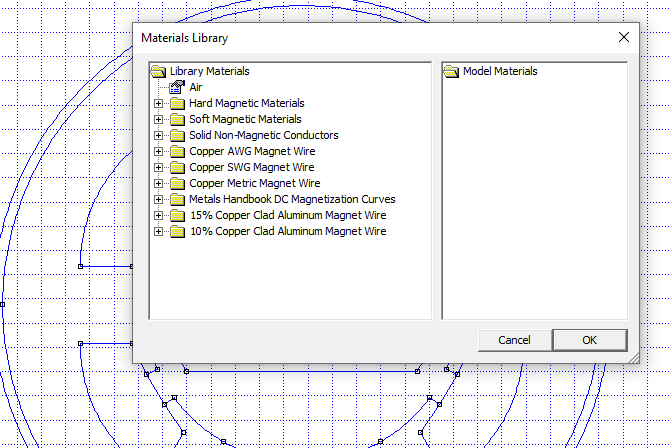

The materials that will be used in the SynRM machine are:

- Soft magnetic steel for stator and rotor core: M-15 Steel

- Copper wire of gauge 20AWG: 20 AWG

- Aluminium for casing: Aluminum, 6061-T6

- Air for the airgaps: Air

Search the materials in the Library tree and drag it to Model Materials on the right sections as follows. Do for all the materials listed above.

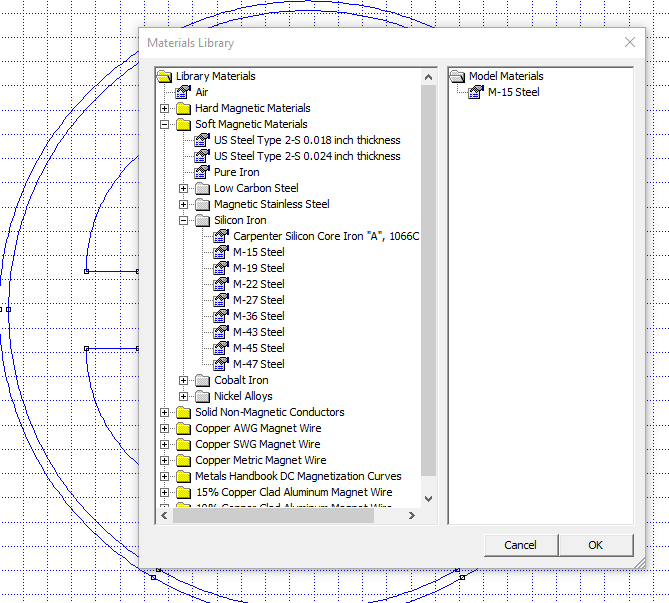

Then, create a block label by clicking on the block button, then click on the region of interest (for example in the figure below, it is the stator core). This creates a block label named <None> automatically. Right click on ot and key 'space bar'. A pop up window will appear where we can select the material to be affected to this region. In this example, it is going to be the M-15 Steel.

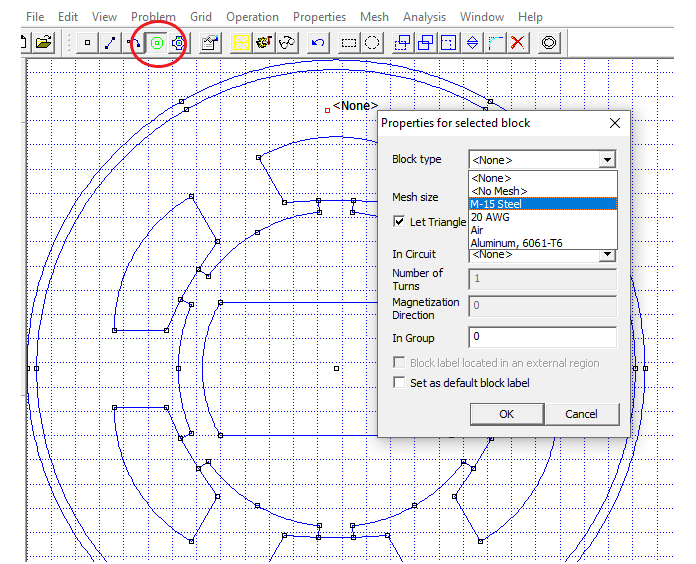

Do the same for the other regions in the list until you have the followings.

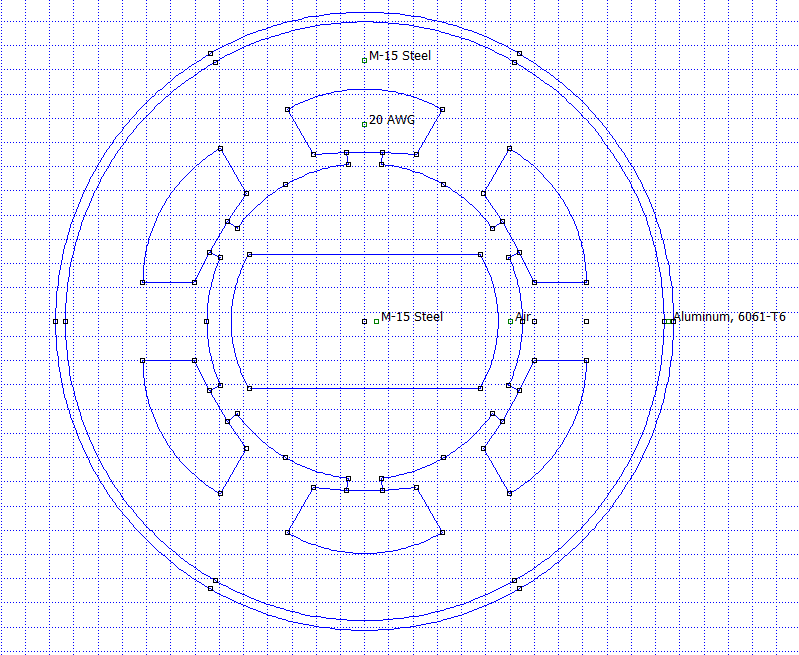 

For the slot winding, instead of repeating the process for the other 5 slots, we can just copy and rotate to place the block labels. To do so, select the 20 AWG block and copy rotate it by 60 degress and make 5 copies like below.

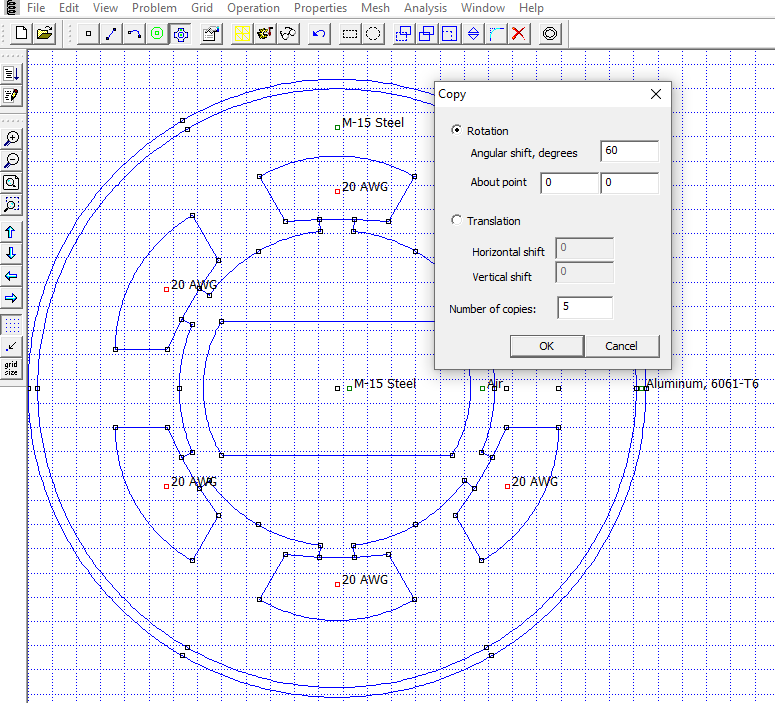

Now, we have defined all the regions with its materials.

### Import materials and defining region using MATLAB command

The materials can be added to the project by using the command mi_getmaterial. The name of the materials in the library need to be known beforehand. The command is  as follows:

%     add material
mi_getmaterial('Air') 
mi_getmaterial('M-15 Steel')
mi_getmaterial('20 AWG')
mi_getmaterial('Aluminum, 6061-T6')

Then, we can add block for regions by using the mi-addblocklabel command and set the block materials by using the command mi_setblockprop. We have to however, select that block first before setting the block materials. After done setting the blovck materials, teh selection need to be released as well. These are done as follows:

mi_addblocklabel(x_rotor + (airgap/2),0);
mi_selectlabel(x_rotor + (airgap/2),0);
mi_setblockprop('Air', 0, 0, '', 0, 1,1);
mi_clearselected;
mi_addblocklabel(1,0);
mi_selectlabel(1,0);
mi_setblockprop('M-15 Steel', 0, 0, '', 0, 1,1);
mi_clearselected;
mi_addblocklabel(0,R_ext_stat-h_yoke_stat/2);
mi_selectlabel(0,R_ext_stat-h_yoke_stat/2);
mi_setblockprop('M-15 Steel', 0, 0, '', 0, 1,1);
mi_clearselected;
mi_addblocklabel(0,R_int_stat+h_yoke_stat/2);
mi_selectlabel(0,R_int_stat+h_yoke_stat/2);
mi_setblockprop('20 AWG', 0, 0, '', 0, 2,1);
mi_clearselected;
mi_addblocklabel(R_ext_stat+thickness_case/2,0);
mi_selectlabel(R_ext_stat+thickness_case/2,0);
mi_setblockprop('Aluminum, 6061-T6', 0, 0, '', 0, 1,1);
mi_clearselected;

To repeat the region setting for other slot winding, the process can be repeated using the mi_copyrotate command as follows:

% rotate slot block setting
mi_selectgroup(2);
mi_copyrotate(0,0,60,5)
mi_clearselected;

## 4. Definition of electrical circuits

Electrical machine is also made of electrical circuit that produce the magneto-motive force that geenrate the magnetic flux. Therefore, we have to define the electricalc circuit and affect it to the proper winding slot. The SynRM is a 3-phase AC machine. The winding arrangements is distributed winding with 10 truns of coil in each slot. The distribution of the current direction is shown in the figure below (left). At the end of this section, we should get something that looks like in the figure on the right. 

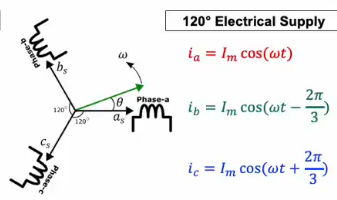    

### Manually defining the electrical circuit

To define manually the circuit, go to the menu 'Properties' --> Circuits. A pop up menu will allow you to create a new circuit property by clicking Add Property. 

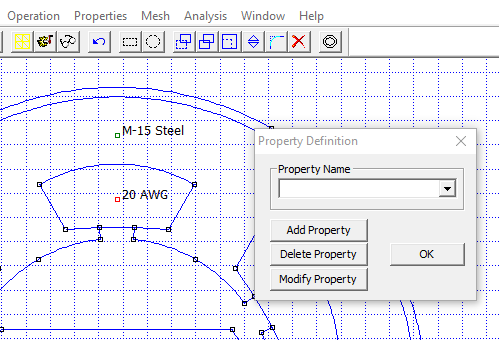

There are 6 circuits in total: A+, A-, B+, B-, C+, C-

The + and - represent the different current direction of the same phase. In each A, B and C phase, they will take the value of a triphase current at any time t. A triphase current can be described as:

Imax = 20;  % peak current (A)
f = 50;    % frequency electric supply in (Hz)
T = 1/f;    % electrical period
s = 100; % sampling per period

for   i = 1:s;  % electrical time for 1 period
    t(i) = i*(T/s);
    i_A = Imax*sin(2*pi*f*t); 
    i_B = Imax*sin(2*pi*f*t - 2*pi/3) ;
    i_C = Imax*sin(2*pi*f*t + 2*pi/3);
end

figure
plot(t, i_A)
hold

Current plot held


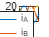

plot(t, i_B)
plot(t, i_C)
grid
legend('i_A','i_B','i_C')

So, we can pick any time t, and take the three values of the voltages for each phase. For example, we will take for t = 0 seconds, from the plot above, we get Va = 0V, Vb = -18V and Vc = 16.7V. -A, -B and -C will simply take the negative values. So for example in the circuit A+, B+ and C+ we define as follows:

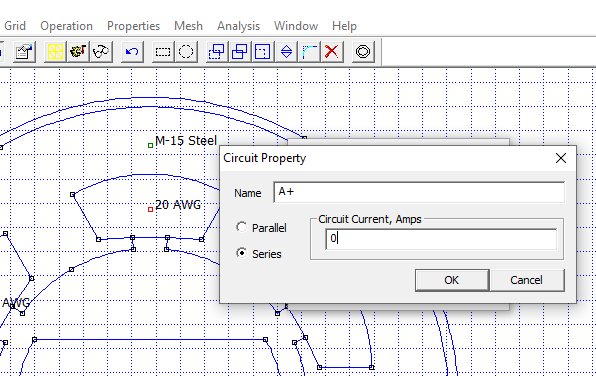  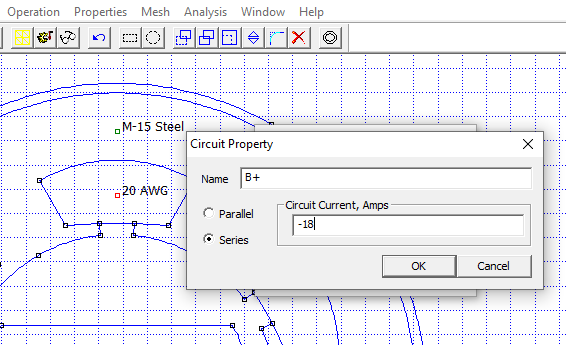

Continue to define for all 6 circuits. In the property, the circuit is in series which means if there are any other slot taking the same circuit property, they will be in series with each other.

Nowthat we have define the circuit, we ghave to affect the circuit to the correct slot winding. To do so, in block mode, select the block of the slot winding and push 'space bar'. The pop up window below will appear. You can then select "In Circuit" to define wich circuit does the slot winding belong to. In this example, the top slot is an A+. Continue to affect the other 5 slot to the correct circuit

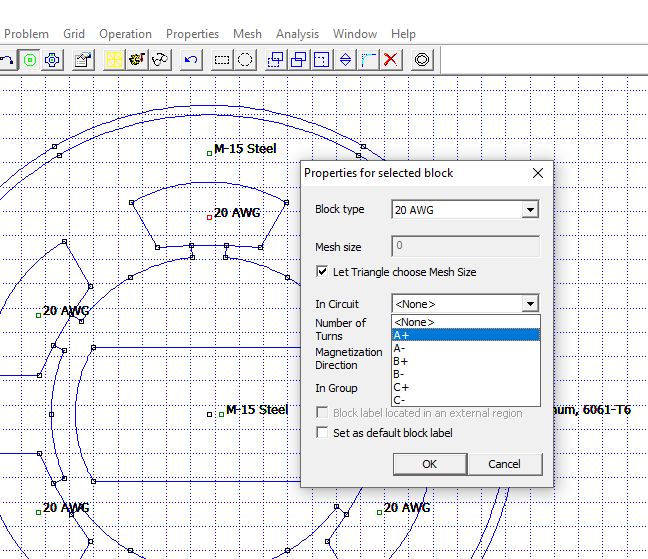

Continue to affect the other 5 slot to the correct circuit until you get as in the following figure.

Now, we have defined all the properties and the machine is ready to be meshed and analyzed by the solver.

### Defining the electrical circuit using MATLAB command

Using MATLAB, we have the advantage of being able to parametrize the circuit property jsut like the geometrical parameters. So we could define and add the circuit properties as follows:

%% Add circuit properties
n = 10; %number of turns
Imax = 20;  % peak current (A)
f = 50;    % frequency electric supply in (Hz)
T = 1/f;   % electrical period (sec) 
load_theta = 0;  % Load angle (rad)
t = T/(2*pi)*load_theta;  % electrical time 
% ----------> DEFINE AS LOAD ANGLE (CONTROL PARAMETERS)
i_A = Imax*sin(2*pi*f*t);
i_B = Imax*sin(2*pi*f*t - 2*pi/3) ;
i_C = Imax*sin(2*pi*f*t + 2*pi/3);
mi_addcircprop('A+', i_A, 1)
mi_addcircprop('A-', -i_A, 1)
mi_addcircprop('B+', i_B, 1)
mi_addcircprop('B-', -i_B, 1)
mi_addcircprop('C+', i_C, 1)
mi_addcircprop('C-', -i_C, 1)


 Remarks: The load angle defined here is an image to time that was defined manually.

Next, the block of the slot winding need to be selected and affected with the corresponding circuits. This is done for all 6 winding slots.

% Slot A+
mi_selectlabel(0,R_int_stat+h_yoke_stat/2);
mi_setblockprop('20 AWG', 0, 0, 'A+', 0, 3,n);
% mi_selectgroup(3);
% mi_copyrotate(0, 0, 180/p, p )            % not necessary if p = 1
mi_clearselected;
% Slot B+
mi_selectlabel((R_int_stat+h_yoke_stat/2)*cos(360/2*p/phi*(pi/180)),(R_int_stat+h_yoke_stat/2)*sin(360/2*p/phi*(pi/180)));
mi_setblockprop('20 AWG', 0, 0, 'B-', 0, 4,n);
mi_clearselected;
% % Slot C+
mi_selectlabel((R_int_stat+h_yoke_stat/2)*cos(360/2*p/phi*(pi/180)),-(R_int_stat+h_yoke_stat/2)*sin(360/2*p/phi*(pi/180)));
mi_setblockprop('20 AWG', 0, 0, 'C+', 0, 5,n);
mi_clearselected;
% % Slot A-
mi_selectlabel(0,-(R_int_stat+h_yoke_stat/2)*sin(360/2*p/phi*(pi/180)));
mi_setblockprop('20 AWG', 0, 0, 'A-', 0, 6,n);
mi_clearselected;
% % Slot B-
mi_selectlabel(-(R_int_stat+h_yoke_stat/2)*cos(360/2*p/phi*(pi/180)),-(R_int_stat+h_yoke_stat/2)*sin(360/2*p/phi*(pi/180)));
mi_setblockprop('20 AWG', 0, 0, 'B+', 0, 7,n);
mi_clearselected;
% % Slot C-
mi_selectlabel(-(R_int_stat+h_yoke_stat/2)*cos(360/2*p/phi*(pi/180)),(R_int_stat+h_yoke_stat/2)*sin(360/2*p/phi*(pi/180)));
mi_setblockprop('20 AWG', 0, 0, 'C-', 0, 8,n);
mi_clearselected;

This should give you at the end as in the figure shown below.

Now, we have defined all the properties and the machine is ready to be meshed and analyzed by the solver.

## 5. Setting boundary condition

The boundary condition is an element that define a segment with a certain magnetic flux condition. For example, we could decide that on the casing, there is bno magnetic flux crossing the casing into the air. This is called 0 flux condition. How ever, with a casing made of aluminium as defined in this example project, the extremely high relative permeability of the stator core in comparison to the realtive permeability of aluminium would automatically contain teh flux inside the motor. So there is no use of creating a boundary condition here.

Examples of how boundaries conditions could be applied for example in airgap will be discussed ina further more advanced modules.

There are also other boundary conditions that could be applied to reduce the size of the model by taking advantage of the symetricity of the machine. This will be discuessed in a more advanced module.

## 6. Meshing and analyzing

Now that we have the complete machine defined with its materials and circuits, we can mesh and analyze it. To mesh, we have to save the file beforehand. Save the file using the name of your preference. It will save it as "Filename.FEM".

### Meshing and analyzing using the manual interface

Click on the mesh button and FEMM will mesh it using automatic mesh parameters. A pop up window will let you know that the meshing is completed and give the information on the number of nodes created.

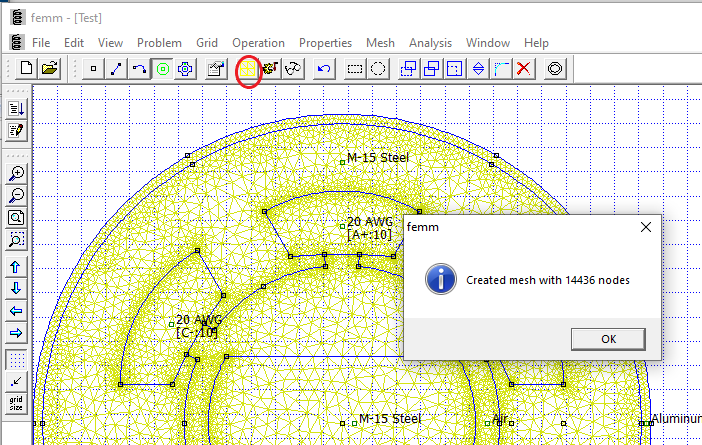

Once, meshed, the problem can be analyzed. Click on the button analyze and a window will show the progress of computation. 

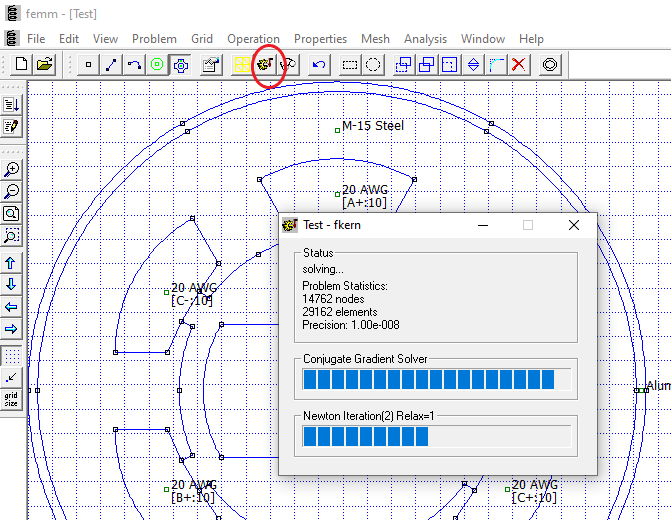

Once the computation completed, we can proceed to the post processing which is analyzing the results.

### Meshing and analyzing using MATLAB command

To mesh and analyze the problem using MATLAB command, enter the following lines:

mi_saveas('Test.fem');
mi_createmesh;
mi_analyze;

Windows will popups showing the meshing and solver computation process until all completed.

## 7. Post-processing: Analyzing results

After completing the computation process by the solver, we can now visualize the reults. Among the results that are important to observe are the flux lines, the distribution/gradient of magnetic field (flux density), the torque and electrical parameters like the inductances.

### Post-processing using the manual interface

Click the button post processing and FEMM will open another window with a plot of flux lines. A small output window will also indicate the problem that was executed.

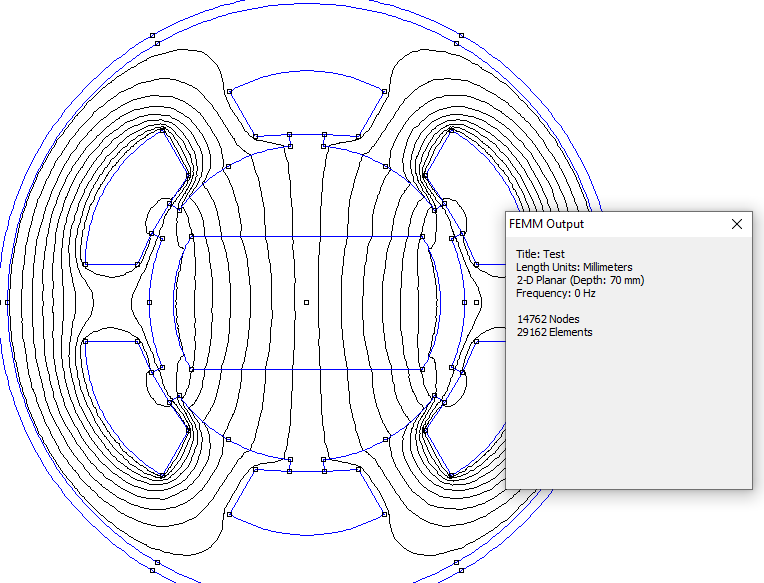

To observe the flux density distribution, click on gradient button and the gradient of the flux density in Tesla will appear with the scaling on top right window. From the figure, we can observe the area of saturation and the path of flux lines.

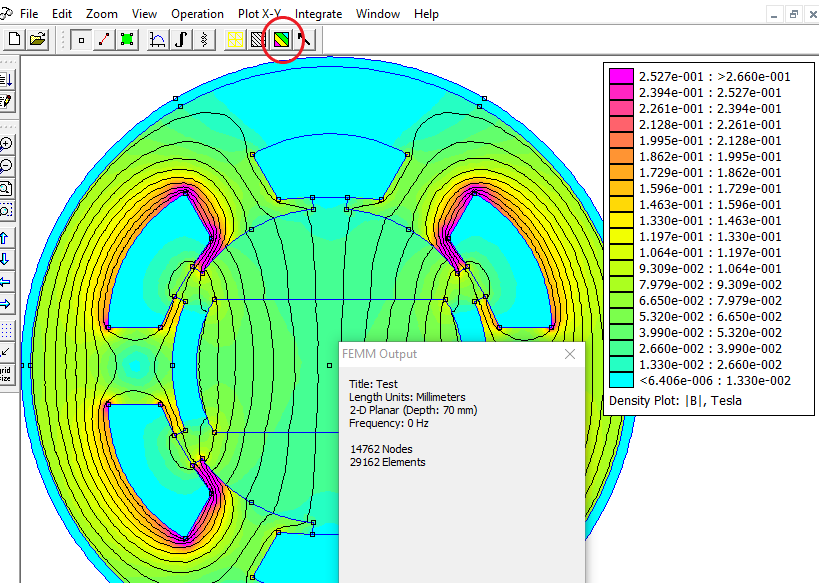

The circuit parameters can be observed by clicking the button circuit. A pop up window allow you to select which circuit you want to observe. Among the parameters that are shown are:

- currents

- voltage drop

- flux linkage

- flux/current = inductance 

- resistance

- power consumed by the circuit

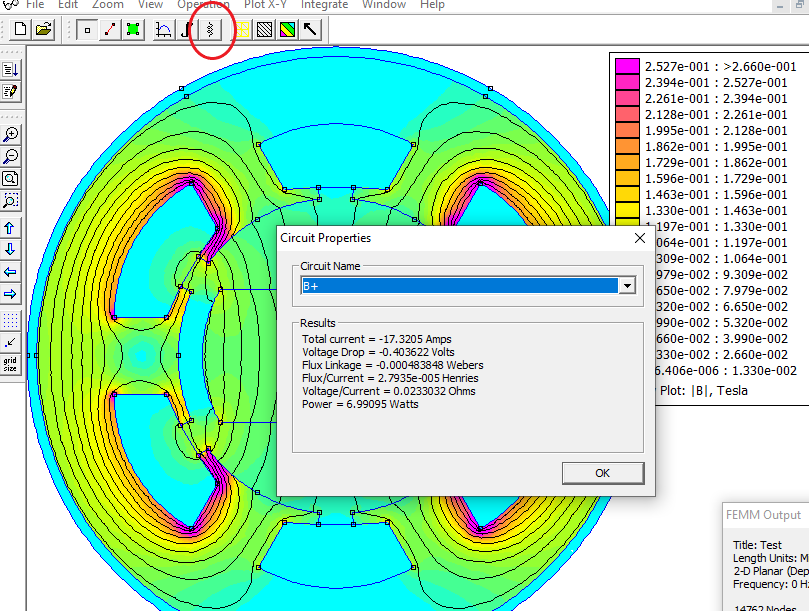

As for mechanical parameters, there are torque that can be computed. It can be computed by first selecting the region on which the torque want to be evaluated by clicking region of interest. Then choosing "Torque by Weighted Stres Tensor".

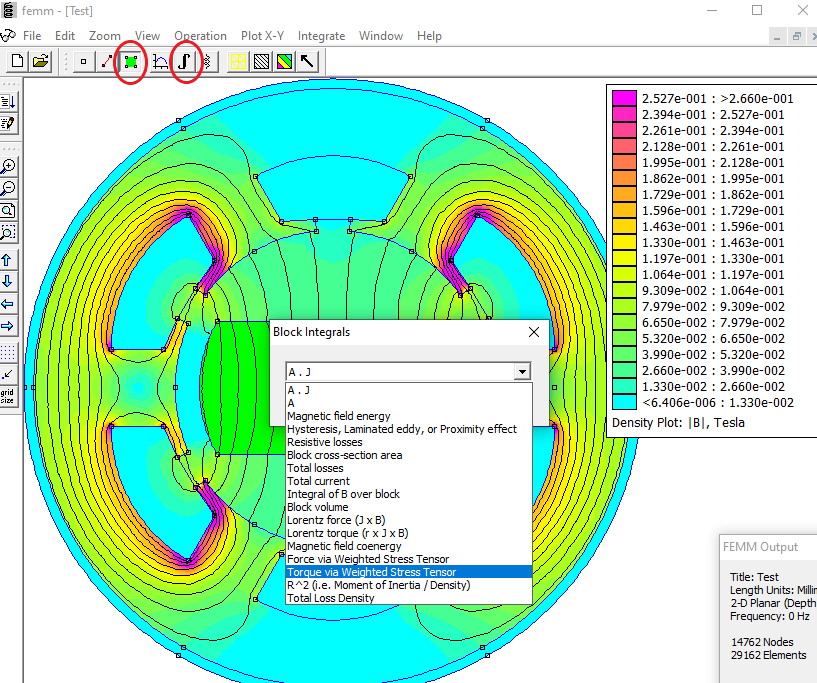  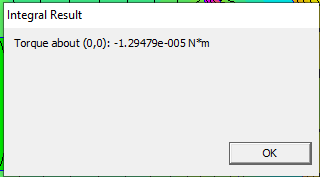

A pop up window will show the torque in N.m. 

**Remarks:** The torque is an instantaneous torque at a specific time t and at a specific rotor position. A torque figure given in a motor datasheet is an aaverage torque.

The torque observed here is very small because the rotor position and the stator current position is parallel to each other.

 Another interesting variable to be observed is the flux linkage in the airgap. To properly monitor the airgap flux linkage, an arc segment need to be created on which the flux linkage will be collected and plotted. Select segments and create a contour around the airgap like in the figure below. Then click on plot field and choose "Magnitude of Flux Density".

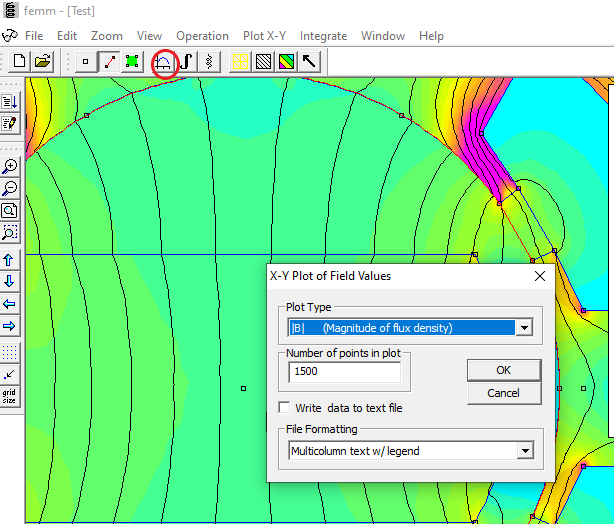

FEMM will open another window with the plot of the flux density across the airgap.

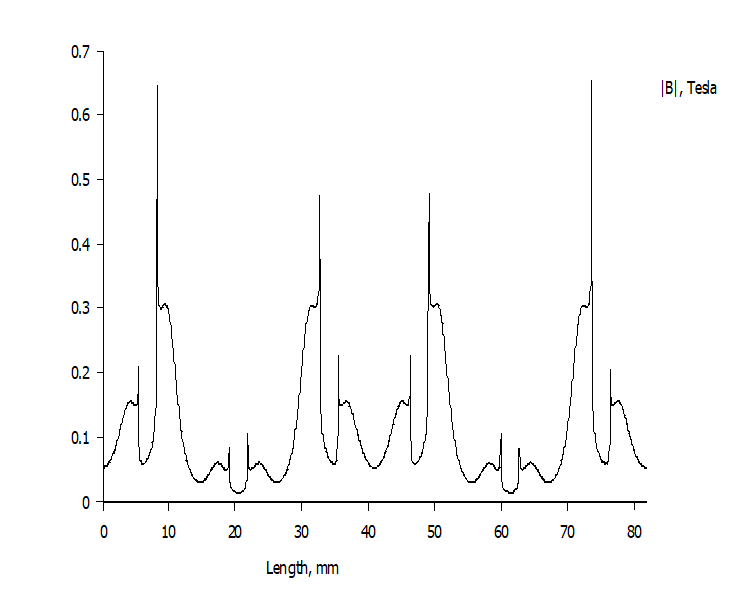

### Post-processing analysis using MATLAB command

MATLAB command to do the post processing analysis are also available in the manual. Example for density plot.

mo_showdensityplot(1,0,0.5,0,'mag');

## Analysis in normal operating condition

### 1.Observing the rotating field

In order to observe the rotating field, manually using the interface, it would need us to change the value of current as the time t changes. This would consume time to do the repetitive task to complete for example one period of current supplied. To reduce the repetitive task, leveraging MATLAB command is the solution.

Exercise: Try to implement a code that would allow us to monitor the rotating magnetic field.

Solution: File "FEMM_Module_1_RMF.m"